clc; clear; close all;
s = tf('s');
P1 = 3/(s+5);
Kp = 5/3;
Ki = 25/3;

C1 = Kp + Ki/s;  

PCL1 = feedback(P1 * C1, 1);
polos = pole(PCL1)

polos =     -5
    -5


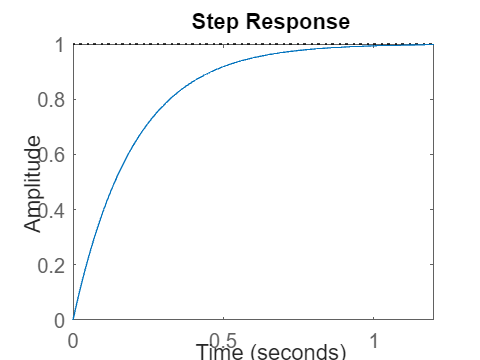


figure;
step(PCL1);


%planta 2
A2 = [0.2 1; 3 4] 

A2 =     0.2000    1.0000
    3.0000    4.0000


B2 = [0.1; 2]

B2 =     0.1000
    2.0000


C2 = [1 3]

C2 =      1     3


D2 = [4]

D2 = 4


P2 = tf(ss(A2,B2,C2,D2))

P2 =
 
  4 s^2 - 10.7 s - 7.5
  --------------------
   s^2 - 4.2 s - 2.2
 
Continuous-time transfer function.
Model Properties


POL2= PCL1*P2;

Gss=ss(POL2)

Gss =
 
  A = 
          x1     x2     x3     x4
   x1   -5.8    4.8  7.938  1.719
   x2      4      0      0      0
   x3      0      4      0      0
   x4      0      0      2      0
 
  B = 
       u1
   x1   8
   x2   0
   x3   0
   x4   0
 
  C = 
            x1       x2       x3       x4
   y1      2.5    1.453   -2.383  -0.7324
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


Qy=100000;
Q_ext=Gss.C'*Qy*Gss.C;
R_ext=0.00001;
K_ext=lqr(Gss.A,Gss.B,Q_ext,R_ext)

K_ext = 1.0e+05 *

    2.5000    5.5177    3.2838    0.7324


Kr_ext=(-(Gss.C-Gss.D*K_ext)*(Gss.A-Gss.B*K_ext)^-1*Gss.B+Gss.D)^-1;
ACL1=Gss.A-Gss.B*K_ext;
BCL1=Gss.B*Kr_ext;
CCL1=Gss.C-Gss.D*K_ext;
DCL1=Gss.D*Kr_ext;
Gss=ss(ACL1,BCL1,CCL1,DCL1);
pole(Gss)

ans = 1.0e+06 *

   -2.0000
   -0.0000
   -0.0000
   -0.0000


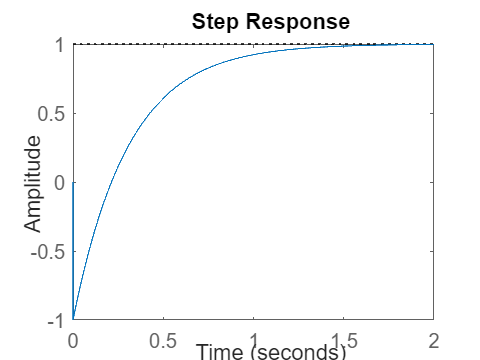

step(Gss)